m = 1:10

m =      1     2     3     4     5     6     7     8     9    10



z = zeros(1,10);
y = zeros(1,10);
for i = 1:10
    K1z = 20*59/(20059*1500)*(1+z(i)^2)^(3/2);
    K2z = 20*59/(20059*1500)*(1+(z(i) + K1z)^2)^(3/2);
    
    z(i+1) = z(i) + 1/2*K1z + 1/2*K2z;

    K1y = 20*z(i);
    K2y = 20*(y(i)+K1y);

    y(i+1) = y(i) + 1/2*K1y*1/2*K2y;
end

z

z = 1.0e-03 *

         0    0.0392    0.0784    0.1177    0.1569    0.1961    0.2353    0.2745    0.3137    0.3530    0.3922


y

y = 1.0e-03 *

         0         0    0.0031    0.0154    0.0433    0.0932    0.1719    0.2867    0.4453    0.6561    0.9284


x = 0:20:200

x =      0    20    40    60    80   100   120   140   160   180   200


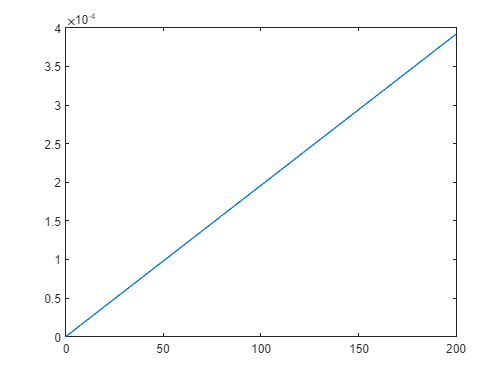

plot(x,z)

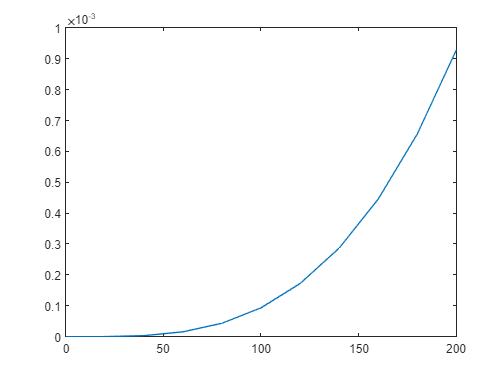

plot(x,y)